EJERCICIO 1

Dado un sistema con dos ceros en -3 y -6 y tres polos en -8 y +3±3j y ganancia estática unitaria, a través del LDR y haciendo uso de sus comandos de Matlab asociados:


% Iniciamos la ft del sistema en lazo cerrado
poloc1 = 3+3i;
poloc2 = 3-3i;

G1 = zpk([-3 -6],[-8 poloc1 poloc2],1);
G2 = feedback(G1,1)


G2 =
 
           (s+3) (s+6)
  ------------------------------
  (s+8.08) (s^2 - 5.08s + 20.05)
 
Continuous-time zero/pole/gain model.
Model Properties


a) Especificar el rango de valores de K que delimitan la estabilidad del sistema en lazo cerrado

% step(G2)
% Despues de observar la respuesta vemos que el sistema es inestable
% Para encontrar una K que delimite la estabilidad del sistema
% Usamos la herramienta rltool

% rltool(G2)

% Gracias a esto encontramos los limites de K en: 
% K > 5.7158 y K < 4.341e+06


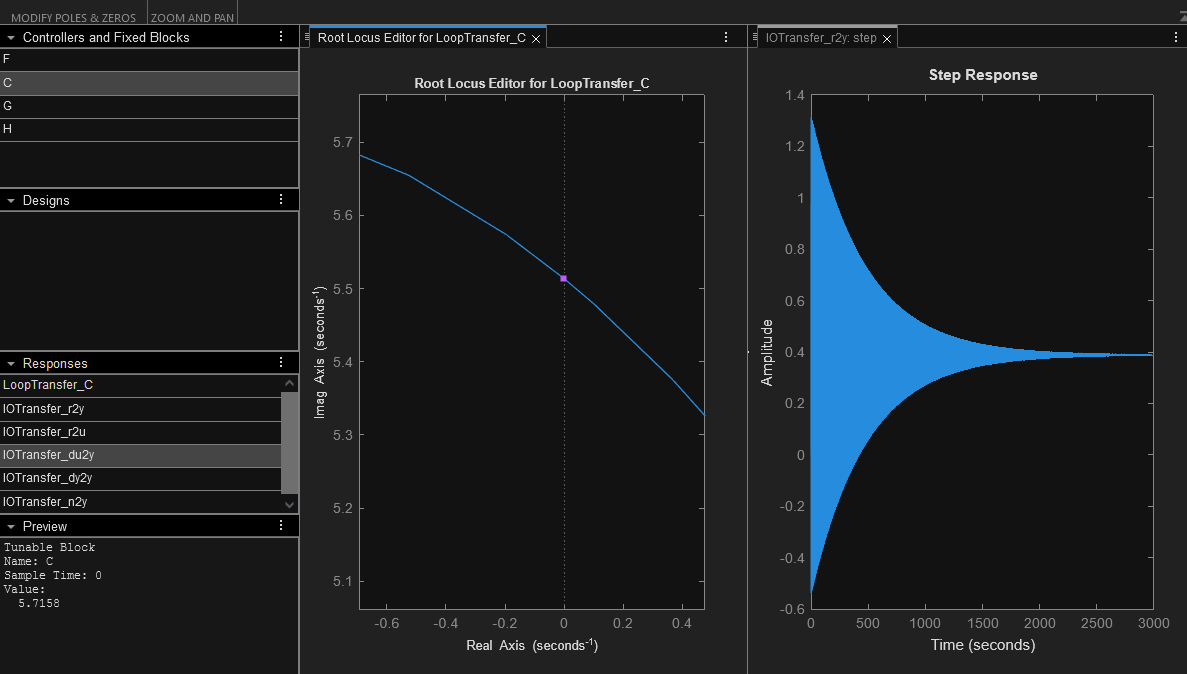

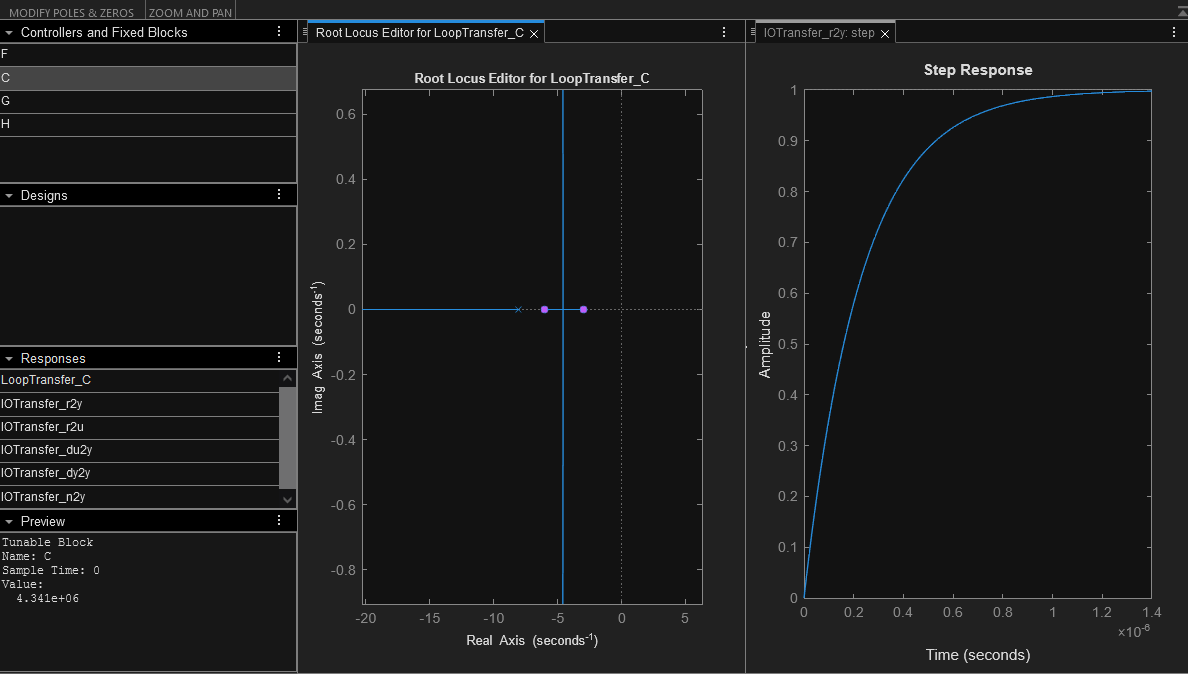

b) Calcular el/los puntos exactos de ruptura y corte con el eje imaginario, así como la ganancia que los provoca

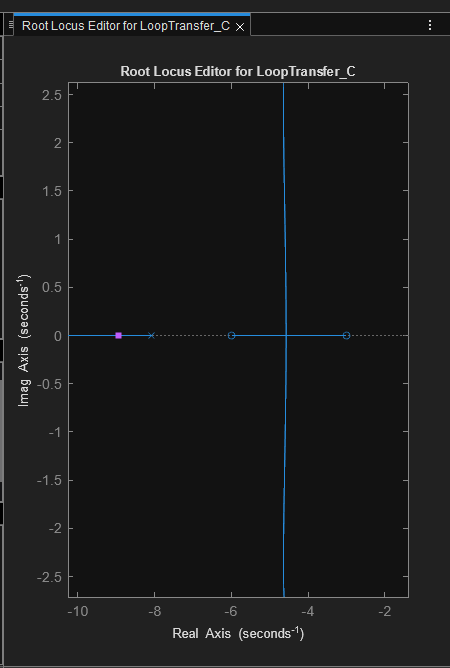

% Usando de nuevo la herramienta RLTOOL observamos que los cortes con el
% eje imaginario son de [-3,-6] y [-8.08,-infinito)
% Observamos tambien que las ganancias que lo definen son 100.3 a 4.341e6

c) Calcular el ángulo de salida del LDR desde los polos complejos conjugados de lazo abierto.

% Primero obtenemos la funcion del sistema en lazo abierto
% Para ello usamos la misma funcion G1 inicial sin el feedback

% Angulos que se forman con el polo de referencia: 3+3j y el eje real

% Angulo del polo en (-8) a p.comp.conj. (3+3j)
alfa1 = atan(3/11);
% Angulo del polo en (3-3j) a p.comp.conj. (3+3j)
alfa2 = 90;
% Angulo del cero en (-6) a p.comp.conj. (3+3j)
beta1 = atan(3/9);
% Angulo del cero en (-3) a p.comp.conj. (3+3j)
beta2 = atan(3/6);

sumAlfa = alfa1 + alfa2;

sumAlfa = 90.2663

sumBeta = beta1 + beta2;

sumBeta = 0.7854


AngSalida = 180 - (sumAlfa - sumBeta)

AngSalida = 90.5191